# **HW09 [ALL CORRECT]**

# Q4

data = [0.90  1.42  1.30  1.55  1.63
        1.32  1.35  1.47  1.95  1.66
        1.96  1.47  1.92  1.35  1.05
        1.85  1.74  1.65  1.78  1.71
        2.29  1.82  2.06  2.14  1.27]

data =     0.9000    1.4200    1.3000    1.5500    1.6300
    1.3200    1.3500    1.4700    1.9500    1.6600
    1.9600    1.4700    1.9200    1.3500    1.0500
    1.8500    1.7400    1.6500    1.7800    1.7100
    2.2900    1.8200    2.0600    2.1400    1.2700



format short

me = mean(data(:))

me = 1.6244

med = median(data(:))

med = 1.6500

mo = mode(data(:))

mo = 1.3500

range = max(data(:)) - min(data(:))

range = 1.3900

std_dev = std(data(:))

std_dev = 0.3394

variance = var(data(:))

variance = 0.1152

cov = (std_dev / me) * 100

cov = 20.8931

# Q1

For the following data:

`>>> x  2  4  6  7  10 11 14 17 20`

`>>> y  4  5  6  5  8  8  6  9  12`

Fit a straight line to the above data and use the result to predict the value of y when x = 5.

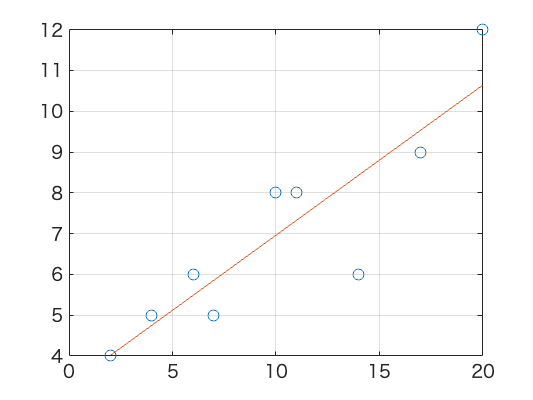

a =     0.3678    3.2807


x = [2 4 6 7 10 11 14 17 20];
y = [4 5 6 5 8 8 6 9 12];

% do linear regression
[a, ~] = linregr(x, y)

y_int = a(2)

y_int = 3.2807

slope = a(1)

slope = 0.3678

xtest1 = 5

xtest1 = 5

ytest1 = slope * xtest1 + y_int % y = mx + c

ytest1 = 5.1199

Derive the least-squares (basically the $y=a_0 +a_1 x+\textrm{error}$ from $y=m\cdot x+c+\textrm{error}$) fit of the following model: $y=a_1 x+e$.

That is, determine the slope that results in the least-squares fit for a straight line with a zero intercept ($a_0 =0$).

Use the least-squares fit to predict the value of y when x = 5.

y_int = 0

y_int = 0

slope = sum(x.*y) / sum(x.^2) % BASED OFF THE a1 FORMULA IN THE LINEAR REGRESSION SLIDES (one with partial derivatives)

slope = 0.6144

xtest = 5

xtest = 5

ytest = slope * xtest + y_int

ytest = 3.0718

# Q2

Table P17.33 lists the 2015 world record times and holders for outdoor running. 

Note that all but the 100 m and the marathon (42,195 m) are run on oval tracks. 

Fit a **power model** for each gender and use it to predict the record time for a half marathon (21,097.5 m).

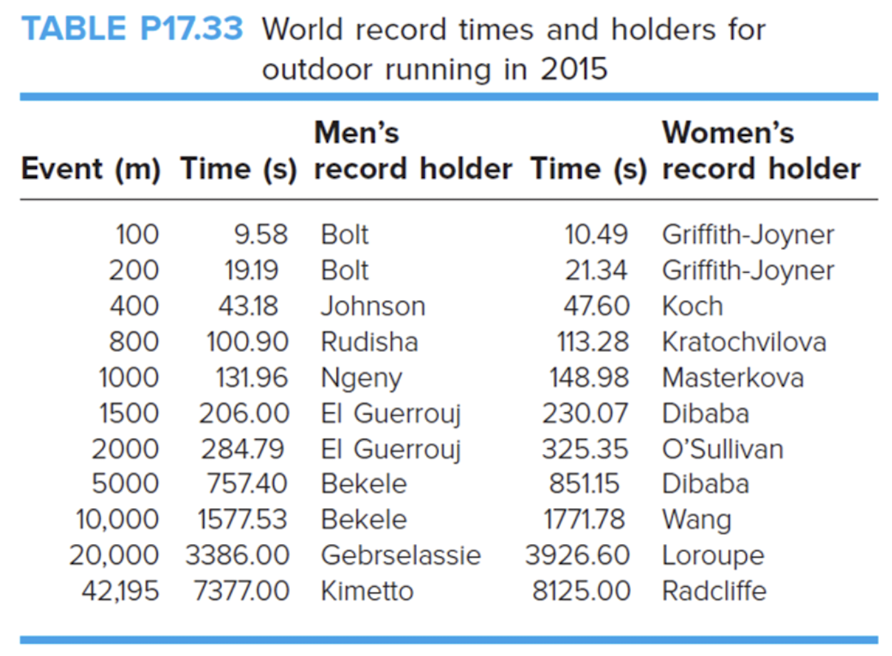

Note that the actual records for the half marathon are 3503 s (Tadese) and 3909 s (Kiplagat) for men and women, respectively. Rounding your calculation to **integers**.


$$\begin{array}{rcl}
t &=& \alpha d^\beta\\
\log(t) &=& \log(\alpha) + \log(d^\beta)\\
\log(t) &=& \log(\alpha) + \beta\log(d) \\
\because \quad y &=& mx+c\ \\
\therefore \quad c &\rightarrow& a_0 = \log_{10}{\alpha} \\
\therefore \quad c &\rightarrow& \alpha = 10^{a_0} &\text{(y-intercept)}&\\
\therefore \quad m &\rightarrow& \beta &\text{(slope)}& \\
\end{array}$$


dist = [100 200 400 800 1000 1500 2000 5000 10000 20000 42195];
time_m = [9.58 19.19 43.18 100.90 131.96 206.00 284.79 757.40 1577.53 3386.00 7377.00];
time_f = [10.49 21.34 47.60 113.28 148.98 230.07 325.35 851.15 1771.78 3926.60 8125.00];

% `log()` = NATURAL log, `exp(k)` = e^k like in Python
[a_m, r2_m] = linregr(log10(dist), log10(time_m)); title('Marathon, Male');

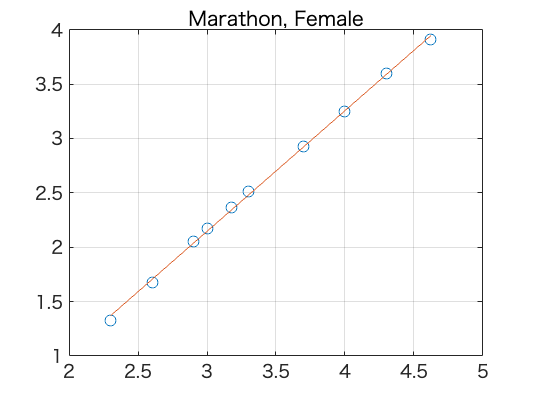

[a_f, r2_f] = linregr(log10(dist), log10(time_f)); title('Marathon, Female');

% output: array `a`
% a(1) = vector of slope
beta_m = a_m(1);
beta_f = a_f(1);
% a(2) = y-intercept
alpha_m = 10^(a_m(2));
alpha_f = 10^(a_f(2));

dist_half = 21097.5; % half marathon
time_pred_m = alpha_m * (dist_half^beta_m);
time_pred_f = alpha_f * (dist_half^beta_f);

fprintf('time_pred_m = %d', round(time_pred_m));

time_pred_m = 3646

fprintf('time_pred_f = %d', round(time_pred_f));

time_pred_f = 4124

# Q3

Use least-squares regression to fit a straight line to

`>>> x  0  2  4  6  9  11  12  15  17  19`

`>>> y  5  6  7  6  9  8   8   10  12  12`

Note that rounding a decimal number to four decimal places (`format short`).

**Q3.1    **Along with the slope and intercept, compute:

- the standard error of the estimate $\left(s_{y|x} =\sqrt{\frac{S_r \;}{n-2}}\;\mathrm{where}\;S_r =\sum {\left(y_i -a_0 -a_1 x_i \right)}^2 \right)$

- the correlation coefficient

**Q3.2    **Then repeat the problem, but regress x versus y—that is, switch the variables. Then compute:

- the standard error of the estimate

- the correlation coefficient

format short

x = [0  2  4  6  9  11  12  15  17  19];
y = [5  6  7  6  9  8   8   10  12  12];


SYX = 0.8511

R2 = 0.9449

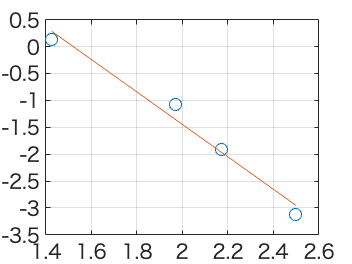

% Y vs X
[a1, r2_1] = linregr(y, x);

xpred = a1(1) * y + a1(2); % mx + c
residuals = x - xpred;
sr = sum(residuals.^2);
syx = sqrt(sr / (length(y) - 2))

syx = 2.2393

r2 = sqrt(r2_1)

r2 = 0.9449


% X vs Y
[a2, r2_2] = linregr(x, y); % x is independent, y is dependent
% predicted y values
YPRED = a2(1) * x + a2(2); % (this is what they meant when they said "swap the variables")
RESIDUALS = y - YPRED;
SR = sum(RESIDUALS.^2);
SYX = sqrt(SR / (length(x) - 2))
R2 = sqrt(r2_2)

# Q5

There are other models that can be linearized using transformations. For example, $y=\alpha {x\cdot e}^{\beta x}$.

Linearize this model and use it to estimate α and β based on the following data. 

`x  0.1   0.2   0.4   0.6   0.9   1.3   1.5   1.7   1.8`

`y  0.75 1.25 1.45 1.25 0.85 0.55 0.35 0.28 0.18`

Rounding a decimal number to four decimal places:          α = ?,    β = ?

Also use the model to predict the value of y when x = 1:    x = 1,    y = ?

x = [0.1  0.2  0.4  0.6  0.9  1.3  1.5  1.7  1.8 ];
y = [0.75 1.25 1.45 1.25 0.85 0.55 0.35 0.28 0.18];

% [a, ~] = linregr(x, y);
% alpha = exp(a(2));
% beta = a(1);
% fprintf('alpha = %.4f', alpha);
% fprintf('beta = %.4f\n', beta);
% 
% y_pred = alpha * exp(beta); % (x is 1)
% fprintf('y_pred = %.4f\n', y_pred);

yy = log(y./x)

yy =     2.0149    1.8326    1.2879    0.7340   -0.0572   -0.8602   -1.4553   -1.8036   -2.3026


[a, ~] = linregr(x, yy);
alpha = exp(a(2))

alpha = 9.6618

beta = a(1)

beta = -2.4733

y_pred = alpha * exp(beta)

y_pred = 0.8145

# Q6

The following data show the relationship between the viscosity of SAE 70 oil and temperature. 

**After taking the logarithm of the data, use linear regression** to find the equation of the line that best fits the data.

`>>> Temperature  26.67    93.33    148.89    315.56`

`>>> Viscosity    1.35     0.085    0.012     0.00075`

Then use the fit model to **predict the viscosity (*****y***** value) when the temperature (*****x***** value) is 50**. Rounding a decimal number to *four decimal places*.

… Viscosity = ?


$$\begin{array}{rcl}
\text{From} \quad \log_{10}{y} &=& \text{slope} \cdot \log_{10}{\text{temp}} + \text{intercept} \\
10^{\log_{10}{y}} &=& 10^{\text{slope} \cdot \log_{10}{\text{temp}} + \text{intercept}} &\because n^{a+b} = n^a \cdot n^b& \\
y &=& 10^{\text{slope} \cdot \log_{10}{\text{temp}}} \cdot 10^{\text{intercept}} \\
y &=& \left( 10^{\log_{10}{\text{temp}}} \right)^\text{slope} \cdot 10^{\text{intercept}} \\
\therefore y &=& \text{temp}^\text{slope} \cdot 10^{\text{intercept}} \\
\end{array}$$


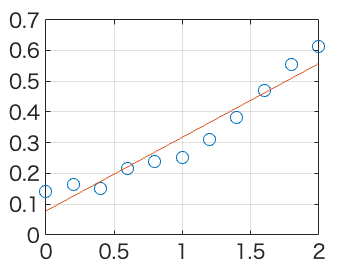

temp = [26.67    93.33    148.89    315.56];
visc = [1.35     0.085    0.012     0.00075];

temp_new = log10(temp);
visc_new = log10(visc);

[vals, r2] = linregr(temp_new, visc_new);

slope = vals(1);
intercept = vals(2);

y_pred = 50^slope * 10^intercept

y_pred = 0.2896

# Q7

There are other models that can be linearized using transformations. For example, the following model applies to third-order chemical reactions in batch reactors: $c=c_0 \left(\frac{1}{\sqrt{1+2{k\cdot c}_0^2 \cdot t}}\right)$.

Where c = concentration, $c_0$ = initial concentration, k = reaction rate, and t = time.

Linearize this model and use it to **estimate k and **$c_0$ based on the following data.

`>>> t = [0     0.5   1     1.5   2     3     4    5]`

`>>> c = [3.26  2.09  1.62  1.48  1.17  1.06  0.9  0.85]`

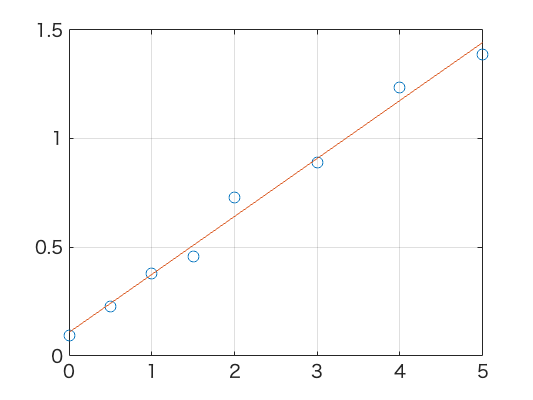

t = [0     0.5   1     1.5   2     3     4    5];
c = [3.26  2.09  1.62  1.48  1.17  1.06  0.9  0.85];

[vals, r2] = linregr(t, 1./(c.^2));

c0 = sqrt(1/vals(2)); k = vals(1)/2;
fprintf('c0 = %.4f\n', c0); fprintf('k = %.4f', k);

c0 = 3.0324
k = 0.1332

# Q8

Fitting the following data with the **exponential model (**$y=\alpha e^{\beta x}$**)**.

`>>> x = [0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000]`

`>>> y = [0.1409    0.1651    0.1506    0.2174    0.2374    0.2517    0.3091    0.3803    0.4700    0.5536    0.6137]`

**Find *****α***** and *****β*****, and the prediction of y when x = 1.1.**

x = [0, 0.2000, 0.4000, 0.6000, 0.8000, 1.0000, 1.2000, 1.4000, 1.6000, 1.8000, 2.0000];
y = [0.1409, 0.1651, 0.1506, 0.2174, 0.2374, 0.2517, 0.3091, 0.3803, 0.4700, 0.5536, 0.6137];

% [vals, r2] = linregr(x, y);
% alpha = exp(vals(2)); beta = vals(1);
% y = log(alpha) + (beta * 1.1) % (x = 1.1)

yy = log(y)

yy =    -1.9597   -1.8012   -1.8931   -1.5260   -1.4380   -1.3795   -1.1741   -0.9668   -0.7550   -0.5913   -0.4882


[a, ~] = linregr(x, yy)

a =     0.7724   -2.0427


% a(1) = slope, a(2) = y-intercept
alpha = exp(a(2))

alpha = 0.1297

beta = a(1)

beta = 0.7724

xtest = 1.1

xtest = 1.1000

y_pred = alpha * exp(beta * xtest)

y_pred = 0.3033